# Plottng Polar Energyscape Example

## Setup scene and sensor

structScene = struct();
structScene.targetAzimuth = [0  -45  45  20  -20  70];
structScene.targetElevation = [0  0    0   0   0    0];
structScene.targetRange    = [2  1.5  1.8 2.5 2.5  3.0];
structScene.targetStrength = [1  1    1   1   1    1  ];
structScene.speedOfSound = 343;

structSensor = struct();
structSensor.sampleRate = 450e3;
structSensor.emissionSignal = clait.fm_sweep(80e3, 20e3, structSensor.sampleRate, 2, 1, 10);
structSensor.coordinatesEmitter = [0 0 0.05];
structSensor.numSamplesSensor = 15000;
structSensor.coordinatesMicrophones = [0 -0.0384 0.0151; 0 -0.0232 0.0101; 0 -0.0121 0.0164; 0 -0.0046 0.0153; ...
                                       0 -0.0367 0.0054; 0 -0.0144 0.0061; 0 0.0054 0.0011; 0 0.0273 -0.0027; ...
                                       0 -0.0387 0.0001; 0 -0.0281 0.0002; 0 -0.0094 -0.0013; 0 -0.0060 -0.0000; ...
                                       0 -0.0357 -0.0117; 0 -0.0318 -0.0112; 0 -0.0286 -0.0166; 0 0.0029 -0.0086; ...
                                       0 -0.0011 0.0178; 0 0.0067 0.0115; 0 0.0103 0.0144; 0 0.0172 0.0140; ...
                                       0 0.0384 0.0022; 0 0.0283 0.0162; 0 0.0354 0.0125; 0 0.0373 0.0150; ...
                                       0 -0.0084 -0.0047; 0 0.0107 -0.0111; 0 0.0189 -0.0166; 0 0.0363 -0.0101; ...
                                       0 0.0057 -0.0224; 0 -0.0036 -0.0223; 0 0.0315 -0.0161; 0 0.0083 -0.0178];
    

## Setup Imaging

structImage = struct();
structImage.directionsAzimuth = -90:2:90;
structImage.directionsElevation = zeros(size(structImage.directionsAzimuth));
structImage.numDirections = length(structImage.directionsAzimuth);
structImage.lowpassFreq = 5e3;
structImage.doEnvelope = 1;
structImage.doThresholdAtZero = 1;
structImage.decimationFactor = 10;
structImage.matchedFilterMethod = 'Normal';
structImage.matchedFilterFreq = [20e3 80e3];
structImage.doMatchedFilter = 1;
structImage.methodImaging = 'DMAS';
structImage.coherenceType = 'CF';
structImage.methodProcessing = 'mexcuda'; 
    

## Generate microphone data

dataMicrophones = simulateMicrophoneData(structScene, structSensor);
dataMicrophones = dataMicrophones + 0.1 * randn(size(dataMicrophones));

## Generate acoustic image

imageDMASCF = clait.calculateAcousticImage(dataMicrophones, structSensor, structImage);

## Query all options

opts = clait.plotPolarEnergyscape('options');

## Example 1: Simple vs advanced plot

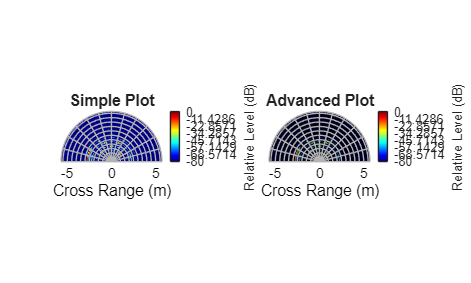

figure();

% Simple plot (no intensity modulation)
subplot(1,2,1);
opts.useSimplePlot = true;
opts.dbCut = -80;
opts.title = 'Simple Plot';
clait.plotPolarEnergyscape(imageDMASCF, structSensor, structImage, opts);

% Advanced plot (with intensity modulation)
subplot(1,2,2);
opts.useSimplePlot = false;
opts.title = 'Advanced Plot';
clait.plotPolarEnergyscape(imageDMASCF, structSensor, structImage, opts);

## Example 2: Simple plot with different colormaps

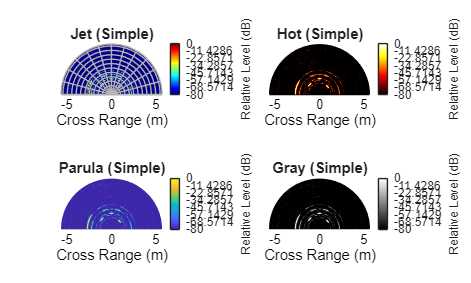

figure();

colormaps = {jet(1024), hot(1024), parula(1024), gray(1024)};
titles = {'Jet (Simple)', 'Hot (Simple)', 'Parula (Simple)', 'Gray (Simple)'};

for i = 1:4
    subplot(2,2,i);
    opts = clait.plotPolarEnergyscape('options');
    opts.useSimplePlot = true;
    opts.dbCut = -80;
    opts.colormap = colormaps{i};
    opts.showGrid = (i == 1);  % Only show grid in first plot
    opts.title = titles{i};
    clait.plotPolarEnergyscape(imageDMASCF, structSensor, structImage, opts);
end

## Example 3: Simple linear scale plot

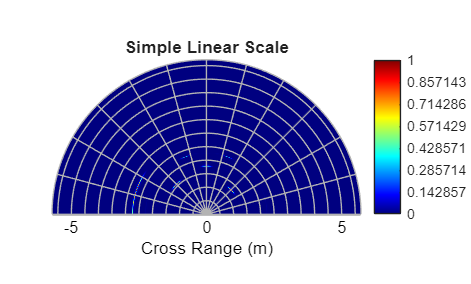

figure();
opts = clait.plotPolarEnergyscape('options');
opts.useSimplePlot = true;
opts.useDbScale = false;  % Linear scale
opts.linearMin = 0;
opts.linearMax = 1;
opts.showGrid = true;
opts.title = 'Simple Linear Scale';
clait.plotPolarEnergyscape(imageDMASCF, structSensor, structImage, opts);

## Example 4: Compare all combinations

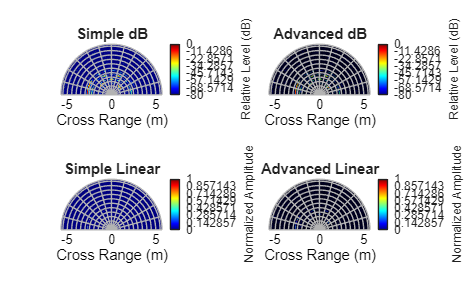

figure();

% dB Simple
subplot(2,2,1);
opts = clait.plotPolarEnergyscape('options');
opts.useSimplePlot = true;
opts.useDbScale = true;
opts.dbCut = -80;
opts.title = 'Simple dB';
clait.plotPolarEnergyscape(imageDMASCF, structSensor, structImage, opts);

% dB Advanced
subplot(2,2,2);
opts.useSimplePlot = false;
opts.title = 'Advanced dB';
clait.plotPolarEnergyscape(imageDMASCF, structSensor, structImage, opts);

% Linear Simple
subplot(2,2,3);
opts.useSimplePlot = true;
opts.useDbScale = false;
opts.title = 'Simple Linear';
clait.plotPolarEnergyscape(imageDMASCF, structSensor, structImage, opts);

% Linear Advanced
subplot(2,2,4);
opts.useSimplePlot = false;
opts.title = 'Advanced Linear';
clait.plotPolarEnergyscape(imageDMASCF, structSensor, structImage, opts);

## Example 5: Simple plot still respects grid and other visual options

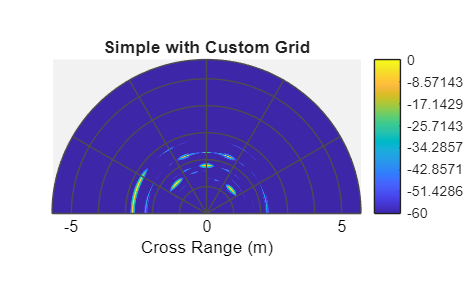

figure();
opts = clait.plotPolarEnergyscape('options');
opts.useSimplePlot = true;
opts.dbCut = -60;
opts.showGrid = true;
opts.gridColor = [0.3 0.3 0.3];
opts.gridRangeSpacing = 1.0;
opts.gridAzimuthSpacing = 30;
opts.backgroundColor = [0.95 0.95 0.95];
opts.colormap = parula(1024);
opts.title = 'Simple with Custom Grid';
clait.plotPolarEnergyscape(imageDMASCF, structSensor, structImage, opts);

## Example 3: Simple linear scale plot

figure();
opts = clait.plotPolarEnergyscape('options');
opts.useSimplePlot = true;
opts.useDbScale = false;  % Linear scale
opts.linearMin = 0;
opts.linearMax = 1;
opts.showGrid = true;
opts.title = 'Simple Linear Scale';
clait.plotPolarEnergyscape(imageDMASCF, structSensor, structImage, opts);